# Lab 2: Simulink

g = 9.81; % Gravitational Constant (magnitude) [m/s^2]
m = 1; % Mass of block in [kg]
k = 4; % Spring coefficient [N/m]
b = 0.5; % Damper coefficient [(N-s)/m]
F = 1; % Magnitude of Force [N]

% angle of ramp
phi = 10 * pi/180; % radians
ramp_angle = phi / (pi/180);

Initial Conditions

x0 = 0;
x_dot0 = 0;
t_end = 10;

m_vals = 0.5:0.5:5; % vector differing of mass in [kg]

% Use a 'for' loop to cycle through the m_vals array
for i = 1:length(m_vals)
    % Select the ith value of m_vals array
    m = m_vals(i);

    % Run simulation with current m, store data in a cell array
    study{i} = sim('mass_ramp',t_end);
end

Plot results

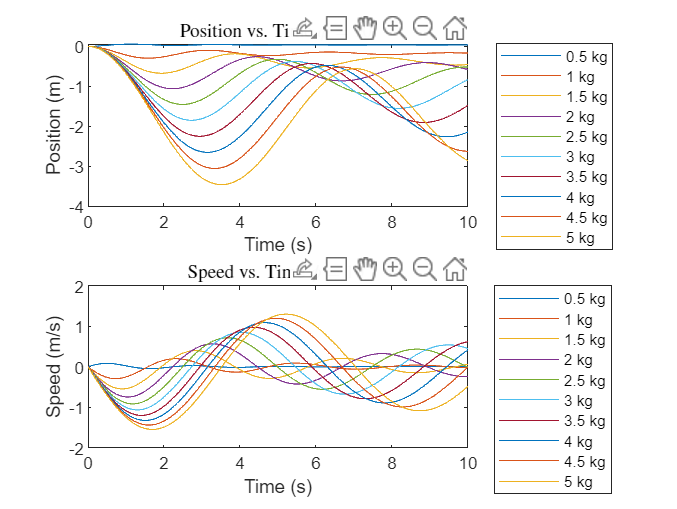

% Use a 'for' loop to cycle through the m_vals array
for i = 1:length(m_vals)
    t = study{i}.tout; % time
    x = study{i}.x.Data; % position
    x_dot = study{i}.x_dot.Data; %speed
    
    % Graph Position vs. Time 
    hold on
    subplot(2, 1, 1)
    plot(t, x)
    title(sprintf("Position vs. Time $\\phi$ = %d$^\\circ$", ramp_angle), "Interpreter","latex")
    xlabel("Time (s)")
    ylabel("Position (m)")
    hold off
    
    % Graph Speed vs. Time 
    hold on
    subplot(2, 1, 2)
    plot(t, x_dot)
    title(sprintf("Speed vs. Time $\\phi$ = %d$^\\circ$", ramp_angle), "Interpreter","latex")
    xlabel("Time (s)")
    ylabel("Speed (m/s)")
    hold off
end

% Add legends
hold on
subplot(2, 1, 1)
legend(string(m_vals) + " kg", Location="eastoutside")
hold off

hold on
subplot(2, 1, 2)    
legend(string(m_vals) + " kg", Location="eastoutside")
hold off